## 0: Loading in Data and preliminary calculations from previous labs

Note that you can modify all of the code to be for the high vs low pt data set by changing data_index. But for the remainder of the lab, all numbers cited and optimized for will be with the low pt data set (data_index = 1).

feature_labels = {'pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', ...
    't1', 't2', 't3', 't21', 't32', 'KtDeltaR'};

data_index = 1;

qcd_data_labels = ["qcd_100000_pt_250_500", "qcd_100000_pt_1000_1200"];
higgs_data_labels = ["higgs_100000_pt_250_500", "higgs_100000_pt_1000_1200"];

qcd_label = qcd_data_labels(data_index);
higgs_label = higgs_data_labels(data_index);

h5disp("data/" + qcd_label +".h5")

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



h5disp("data/" + higgs_label +".h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



qcd_data = h5read("data/" + qcd_label+".h5", ['/' convertStringsToChars(qcd_label)]);
higgs_data = h5read("data/" + higgs_label +".h5",['/' convertStringsToChars(higgs_label)]);

% puts in form so first index is for each data point, second is for each
% quantity measured
qcd_data = qcd_data';
higgs_data = higgs_data';


## 1: Mass Comparison of Higgs vs QCD Background and Initial Significance

Below is a calculation taken from lab 5 in which we calculated the significance of detecting the Higgs with no cuts.


n_higgs_list = [100, 50];
n_qcd_list = [20000, 2000];

n_higgs = n_higgs_list(data_index);
n_qcd = n_qcd_list(data_index);

background_prob_to_observe_total = 1- poisscdf(n_qcd + n_higgs, n_qcd)

background_prob_to_observe_total = 0.2385


no_cut_significance = norminv(1-background_prob_to_observe_total)

no_cut_significance = 0.7112

snr = n_higgs / sqrt(n_qcd)

snr = 0.7071

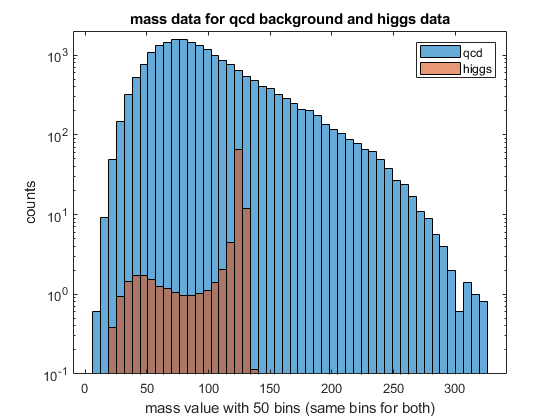


qcd_mass_data = qcd_data(:, 4);
higgs_mass_data = higgs_data(:, 4);

qcd_normalization_ratio = n_qcd/length(qcd_mass_data);
higgs_normalization_ratio = n_higgs/length(higgs_mass_data);

label = feature_labels{4};
nbins = 50;

[~, full_hist_bins] = histcounts([qcd_mass_data, higgs_mass_data], nbins);

mass_full_hist_bins = full_hist_bins;

figure
qcd_mass_hist_counts = histcounts(qcd_mass_data, full_hist_bins);
normalized_qcd_mass_hist_counts = (qcd_normalization_ratio*qcd_mass_hist_counts);

higgs_mass_hist_counts = histcounts(higgs_mass_data, full_hist_bins);
normalized_higgs_mass_hist_counts = ...
    (higgs_normalization_ratio*higgs_mass_hist_counts);

histogram('BinCounts',normalized_qcd_mass_hist_counts, 'BinEdges',full_hist_bins)
hold on
histogram('BinCounts',normalized_higgs_mass_hist_counts, 'BinEdges',full_hist_bins)

title([label ' data for qcd background and higgs data'])
xlabel([label ' value with ' num2str(nbins) ' bins (same bins for both)'])
ylabel('counts')
ylim([0.1, 2*10^3])
set(gca, 'Yscale', 'log')
legend({'qcd', 'higgs'})

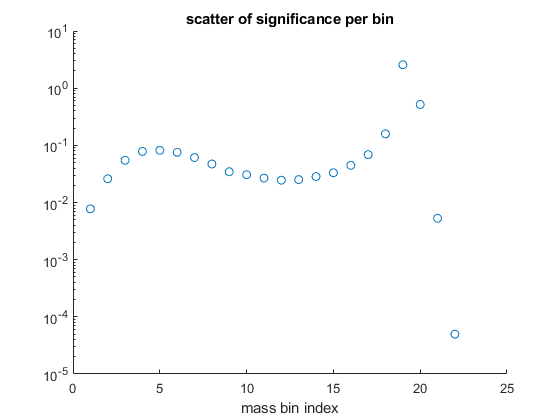

mass_bins_to_use_list = find(normalized_higgs_mass_hist_counts ~= 0);
per_bin_significance = normalized_higgs_mass_hist_counts ./ normalized_qcd_mass_hist_counts.^(1/2);

figure

scatter(mass_bins_to_use_list, per_bin_significance(mass_bins_to_use_list))
title('scatter of significance per bin')
xlabel('mass bin index')
set(gca, 'Yscale', 'log')
datacursormode on

## 2. Identifying mass cuts to optimize expected significance

We will look at subsets of the bins from the histogram above to calculate the optimal mass cuts. I will again be using the restrict data function that I created in lab 5, included at the end of this lab. I start by using the maximum value of the higgs mass data to immediately throw out a large portion of the background data. Then, because of the relative few bins that actually have higgs events, it is possible to brute force over all combinations of those to find their significances. 


no_higgs_bins = find(normalized_higgs_mass_hist_counts == 0);

mass_bins_to_use_list = find(normalized_higgs_mass_hist_counts ~= 0);

bin_inclusion_number = 2^(length(mass_bins_to_use_list)-1);

bin_inclusion_binary_list = logical(de2bi(1:bin_inclusion_number));

significance_list = zeros(1, bin_inclusion_number);
nhiggs_per_cut_list = zeros(1, bin_inclusion_number);
nbackground_per_cut_list = zeros(1, bin_inclusion_number);

for i = 1:bin_inclusion_number
    bin_inclusion_binary = bin_inclusion_binary_list(i, :);
    mass_bins_to_use = mass_bins_to_use_list(bin_inclusion_binary);
    nhiggs = sum(normalized_higgs_mass_hist_counts(mass_bins_to_use));
    nbackground = sum(normalized_qcd_mass_hist_counts(mass_bins_to_use));
    
    nbackground_per_cut_list(i) = nbackground;
    nhiggs_per_cut_list(i) = nhiggs;
    significance_list(i) = nhiggs / sqrt(nbackground);
    mass_significance(i).bins = mass_bins_to_use;
end

Looking at a histogram of the significances for different mass cuts, we see that the best we can do with just a mass cut is around a significance estimate of around 2.5.

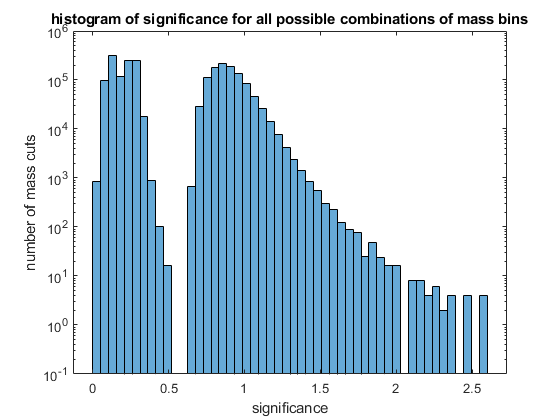

nbins = 50;
figure
[hist_vals, hist_bin_edges] = histcounts(significance_list,nbins);
histogram('BinCounts', hist_vals, 'BinEdges',hist_bin_edges)
title('histogram of significance for all possible combinations of mass bins')
xlabel('significance')
ylabel('number of mass cuts')
ylim([0.1, 10^6])
set(gca, 'YScale', 'log')
datacursormode on

Below I plot significance vs number of higgs events kept. While it might seem that the best place to start is the cut with the most significance, if we are doing a second cut later and there is any correlation between the two parameters, it might be important to start with a less restrictive cut. That being said, for similar significance values, it seems intuitive to use the cut that include the most higgs events. Furthermore, the plot is interesting. We see two similarly shaped higgs events vs significance sections that are distinct. This can arise due to a particular bin in the mass cuts that has a lot of higgs events

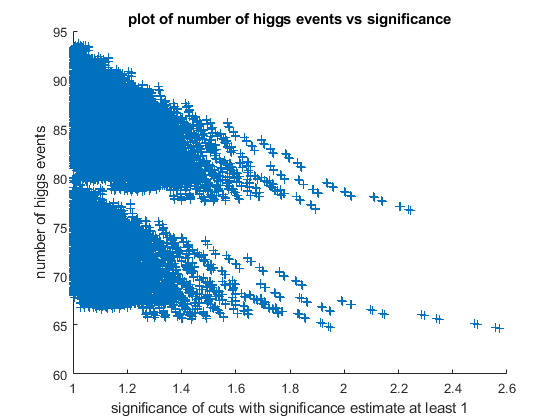

significance_threshold = 1;

more_significant_cuts = find(significance_list > significance_threshold);

restricted_significances = significance_list(more_significant_cuts);
restricted_nhiggs = nhiggs_per_cut_list(more_significant_cuts);
restricted_nbackground = nbackground_per_cut_list(more_significant_cuts);

figure
scatter(restricted_significances, restricted_nhiggs, '+')
title('plot of number of higgs events vs significance')
xlabel(['significance of cuts with significance estimate at least ' num2str(significance_threshold)])
ylabel('number of higgs events')
datacursormode on

From the above plot of higgs events vs significance and the earlier significance per bin scatter plot.

mass_cut_bins = [4,5,6,18,19,20];

mass_cut_nhiggs = sum(normalized_higgs_mass_hist_counts(mass_cut_bins))

mass_cut_nhiggs = 85.1970

mass_cut_nbackground = sum(normalized_qcd_mass_hist_counts(mass_cut_bins))

mass_cut_nbackground = 2.9234e+03

mass_cut_significance = mass_cut_nhiggs / sqrt(mass_cut_nbackground)

mass_cut_significance = 1.5757

## 3. Making stacked histogram plots for other features

Without any mass cuts, we below overplot the qcd and higgs data:

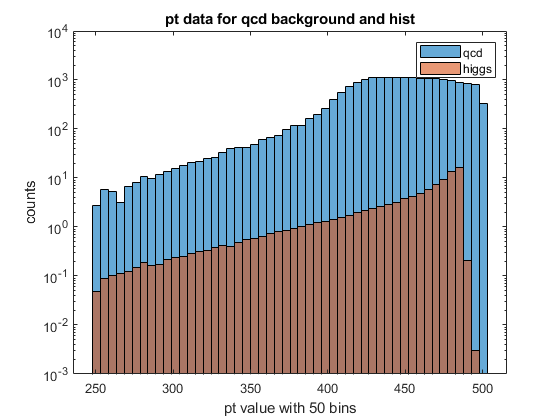

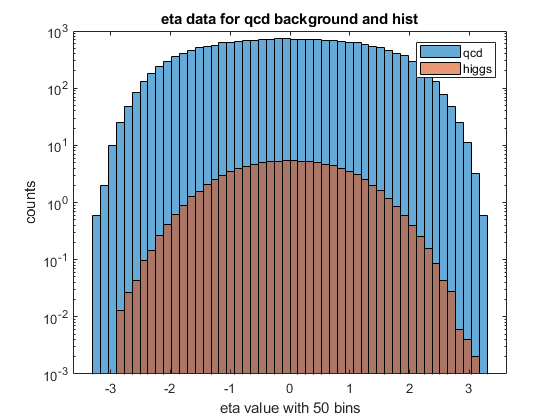

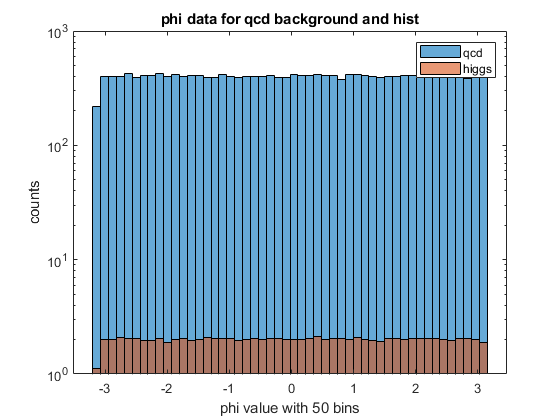

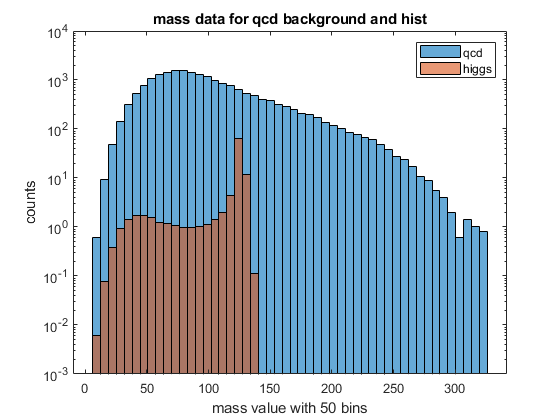

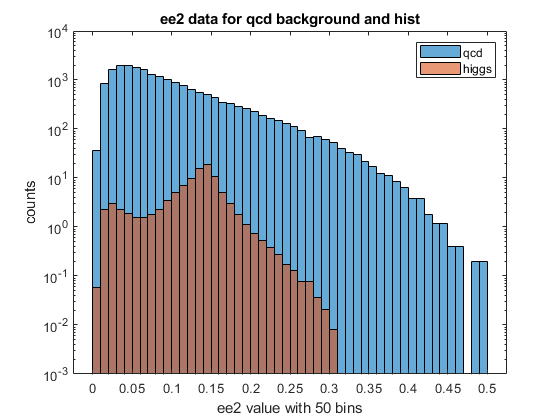

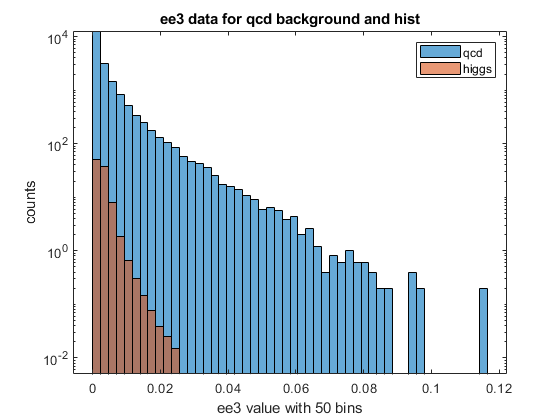

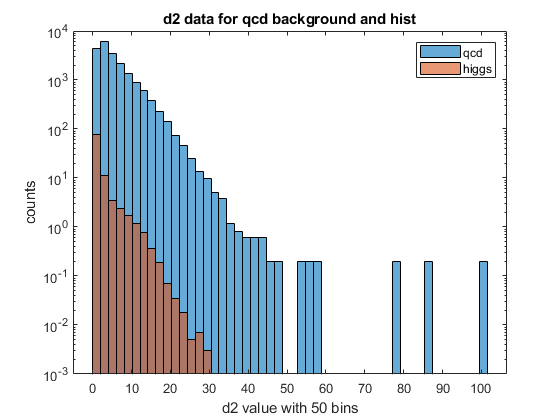

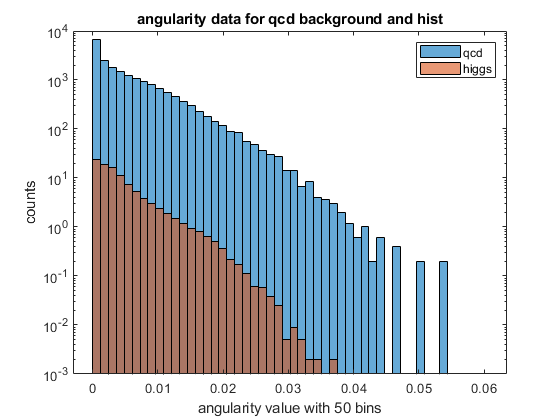

for i=1:length(feature_labels)
    
    label = feature_labels{i};
    nbins = 50;
    
    feature_qcd_data = qcd_data(:, i);
    feature_higgs_data = higgs_data(:, i);
    
    [~, full_hist_bins] = histcounts([feature_qcd_data, feature_higgs_data], nbins);
    figure
    
    qcd_hist_counts = histcounts(feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (qcd_normalization_ratio*qcd_hist_counts);
    
    higgs_hist_counts = histcounts(feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (higgs_normalization_ratio*higgs_hist_counts);
    
    histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins)
    hold on
    histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins)
    

    title([label ' data for qcd background and hist'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'qcd', 'higgs'})

    
end

Now we first restrict the data using a mass cut from earlier, and again look at the overplot of the higgs data and the qcd data. 

% mass_cut_bins : 1D array with bin indices from mass_full_hist_bins
% included in mass cut

% mass_full_hist_bins : 1D array with edges of mass hist bins

mass_included_ranges = zeros(2, length(mass_cut_bins));

mass_included_ranges =      0     0     0     0     0     0
     0     0     0     0     0     0


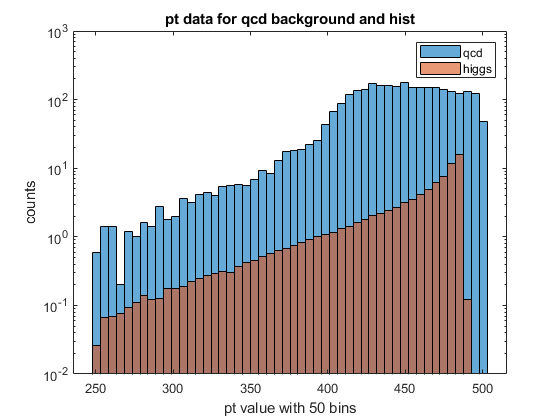

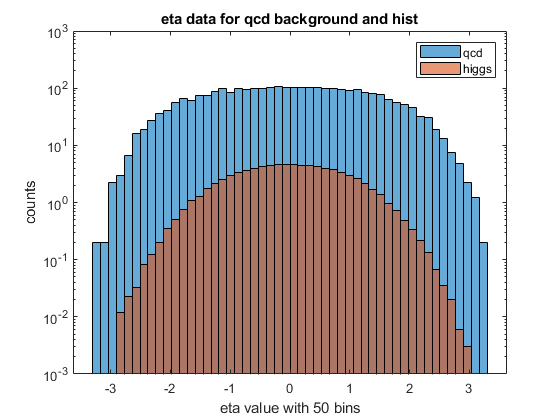

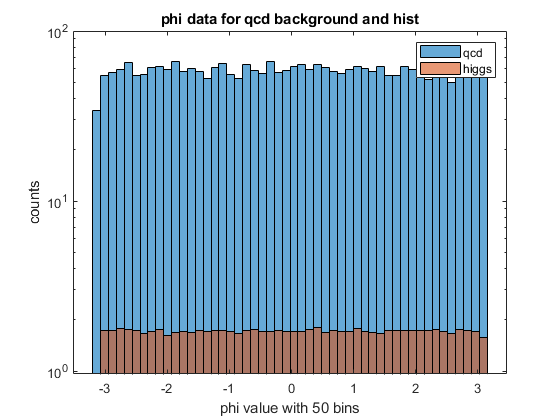

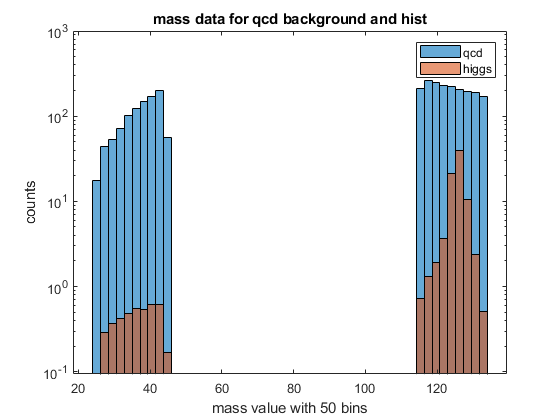

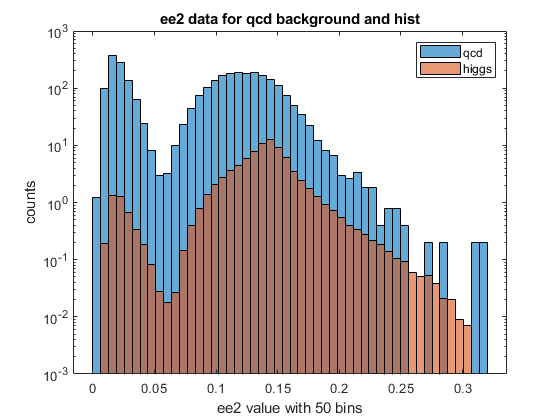

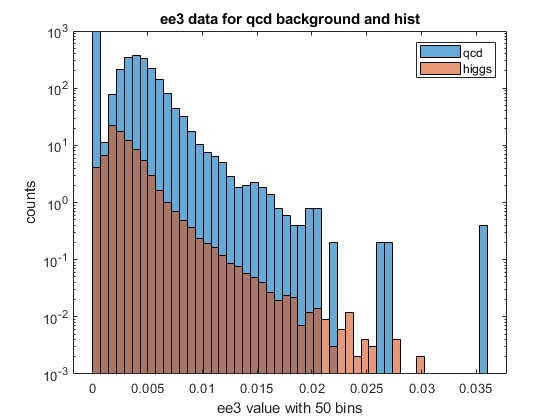

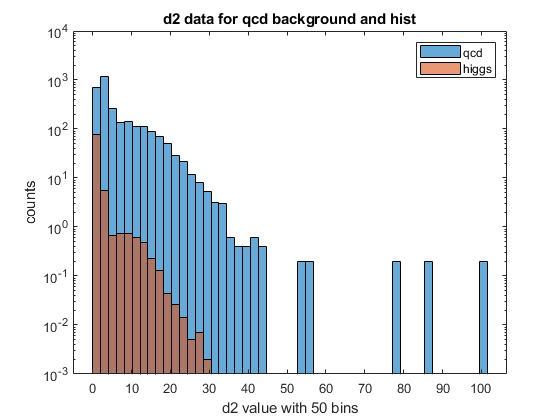

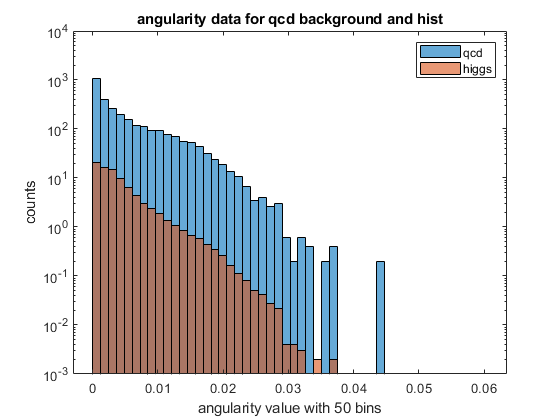


for j = 1:length(mass_cut_bins)
    mass_included_ranges(1, j) = mass_full_hist_bins(mass_cut_bins(j));
    mass_included_ranges(2, j) = mass_full_hist_bins(mass_cut_bins(j)+1);
end

mass_index = 4;

qcd_data_restricted = restrict_data(qcd_data, mass_index, mass_included_ranges);
higgs_data_restricted = restrict_data(higgs_data, mass_index, mass_included_ranges);

for i=1:length(feature_labels)
    
    label = feature_labels{i};
    nbins = 50;
    
    feature_qcd_data = qcd_data_restricted(:, i);
    feature_higgs_data = higgs_data_restricted(:, i);
    
    [~, full_hist_bins] = histcounts([feature_qcd_data', feature_higgs_data'], nbins);
    figure
    
    qcd_hist_counts = histcounts(feature_qcd_data, full_hist_bins);
    normalized_qcd_hist_counts = (qcd_normalization_ratio*qcd_hist_counts);
    
    higgs_hist_counts = histcounts(feature_higgs_data, full_hist_bins);
    normalized_higgs_hist_counts = ...
        (higgs_normalization_ratio*higgs_hist_counts);
    
    if i ~= 4
        histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',full_hist_bins)
        hold on
        histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',full_hist_bins)
    else
        histogram('BinCounts',normalized_qcd_hist_counts, 'BinEdges',mass_full_hist_bins)
        hold on
        histogram('BinCounts',normalized_higgs_hist_counts, 'BinEdges',mass_full_hist_bins)

    title([label ' data for qcd background and hist'])
    xlabel([label ' value with ' num2str(nbins) ' bins'])
    ylabel('counts')
    set(gca, 'Yscale', 'log')
    
    legend({'qcd', 'higgs'})

    
end

## 4. Optimizing Event Selections Using Multiple Features

## 5. 2 Dimensional Cuts for Most Discriminative Features

function [restricted_data] = restrict_data(data, value_index, value_range_list)

Function definition not supported in this context. Create functions in code file.

    % data: each row is a data point with each column a different quantity
    % value_index: from 1:14, indicates which column we are looking at
    % value_range_list: a (2:n) list. each (:, i) indicates a lower and
    % upper bound for a range of values that the data point can fall in
    
    values = data(:, value_index);
    size_value_range_list = size(value_range_list);
    is_included = zeros(length(values),1);
    
    for i=1:size_value_range_list(2)
        lb = value_range_list(1, i);
        ub = value_range_list(2, i);
        above_lb = values > lb;
        below_ub = values < ub;
        in_range = above_lb & below_ub;
        is_included = is_included | in_range;
    end
    
    included_indices = is_included;
    
    restricted_data = data(included_indices, :);
end